clear all;close all;clc;

first_frame=1;  final_frame=206;
height_min=0;  height_max=1.5;
ptcloud_dis_range_min=1;  ptcloud_dis_range_max=5;
p=[];

for i=first_frame:12:final_frame
    i
  
    data=csvread(['C:\Users\5254\Desktop\18-7-10\2019-07-10-21-31-57_Velodyne-VLP-16-Data\data (' num2str(i) ').csv'],1,0);
   
    data=[data(:,4),data(:,5),data(:,6),data(:,7)];
    x=data(:,1);y=data(:,2);z=data(:,3);ptcloud_dis = data(:,4);
    data=[x(ptcloud_dis_range_min<ptcloud_dis&ptcloud_dis<ptcloud_dis_range_max),...
        y(ptcloud_dis_range_min<ptcloud_dis&ptcloud_dis<ptcloud_dis_range_max),...
        z(ptcloud_dis_range_min<ptcloud_dis&ptcloud_dis<ptcloud_dis_range_max)   ];
    x=data(:,1);y=data(:,2);z=data(:,3);
    dataref=[x(height_min<z&z<height_max),y(height_min<z&z<height_max),z(height_min<z&z<height_max)];
    dataref=[dataref(:,1),dataref(:,2)];
    p=[p;x,y];
    
end

i = 1

i = 13

i = 25

i = 37

i = 49

i = 61

i = 73

i = 85

i = 97

i = 109

i = 121

i = 133

i = 145

i = 157

i = 169

i = 181

i = 193

i = 205

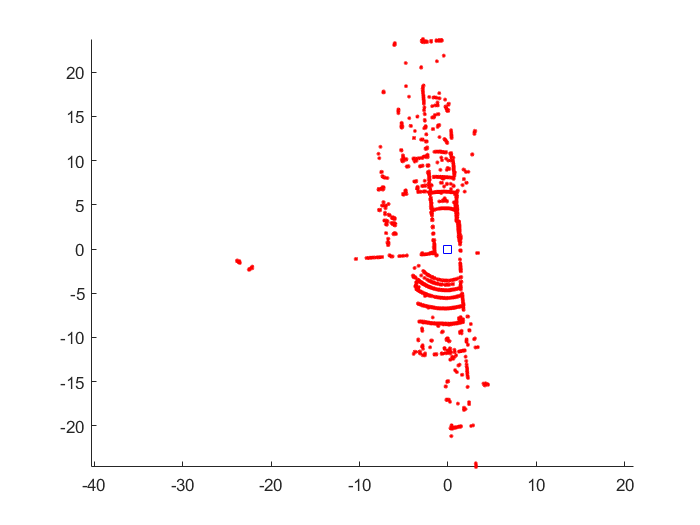


% turn_init = -0.5;
% RotMat  = [ cos(turn_init)  -sin(turn_init);...
%     sin(turn_init)   cos(turn_init)];
% p=[p(:,1),p(:,2)]*RotMat;

hold on
axis equal
plot(p(:,1),p(:,2),'r.')
plot(0,0,'bs')